clc
clear
posSFromP = [0 0.2 0.2];
orientSfromP = quaternion([3,0,0],'eulerd','ZYX','frame')

orientSfromP = quaternion
      0.99966 +        0i +        0j + 0.026177k



posPlat = [0 0 0];
orientPlat = quaternion(1, 0, 0, 0);
velPlat = [0 0 0];
accPlat = [0 0 0];
angvelPlat = [pi 0 0];

[posIMU, orientIMU, velIMU, accIMU, angvelIMU] = transformMotion( ...
    posSFromP, orientSfromP, ...
    posPlat, orientPlat, velPlat, accPlat, angvelPlat);

rotMMis = eul2rotm([pi/40 pi/40 0]);

isFirst = 1;
diffwxs = zeros(100,1);
diffwys = zeros(100,1);
diffvxs = zeros(100,1);
diffvys = zeros(100,1);

for i=1:100
    
    angvelIMU = (rotMMis * angvelPlat') + (-0.01+0.02.*rand(3,1));
    velIMU_ = velIMU'+ (-0.01+0.02.*rand(3,1));
    
    A = matW(pi+0.01.*rand(1));
    B = [angvelIMU(2) angvelIMU(3) velIMU_(2) velIMU_(3)]';
    
    if(isFirst)
        [X,S,V] = IMU_RTLS(A,B,0,0,1);
        diffwxs(i) = X(1)-(pi/40);
        diffwys(i) = X(2)-(pi/40);
        diffvxs(i) = X(3)+0.2;
        diffvys(i) = X(4)+0.2;
        isFirst = 0;
    else
        [X,S,V] = IMU_RTLS(A,B,S,V,0);
        diffwxs(i) = X(1)-(pi/40);
        diffwys(i) = X(2)-(pi/40);
        diffvxs(i) = X(3)+0.2;
        diffvys(i) = X(4)+0.2;
    end
end

U =     0.2614         0         0    0.9652
   -0.2639    0.6780    0.6824    0.0714
   -0.6586    0.3633   -0.6344    0.1783
    0.6544    0.6390   -0.3633   -0.1772


S =     3.2940         0         0         0         0
         0    3.1486         0         0         0
         0         0    3.1486         0         0
         0         0         0    3.1486         0


V =     0.2522   -0.6780   -0.6824   -0.0714   -0.0775
    0.2498   -0.0000   -0.0000    0.9652   -0.0768
   -0.6255   -0.6390    0.3633    0.1772    0.1923
   -0.6296    0.3633   -0.6344    0.1783    0.1935
    0.2938    0.0000    0.0000   -0.0000    0.9559


first S size is: 4 x 5


X =     0.0811
    0.0803
   -0.2012
   -0.2024


S_ size is: 4 x 5
a size is: 5 x 4
M size is: 8 x 5


S =     4.6428         0         0         0         0
         0    4.4413         0         0         0
         0         0    4.4413         0         0
         0         0         0    4.4413         0
         0         0         0         0    0.0144


V =    -0.2475   -0.2819   -0.7939    0.4726   -0.0754
   -0.2530    0.2404    0.4784    0.8021   -0.0771
    0.6280    0.6500   -0.3187    0.2117    0.1913
    0.6288   -0.6635    0.1984    0.2973    0.1916
   -0.2914    0.0000    0.0000   -0.0000    0.9566


X =     0.0788
    0.0806
   -0.2000
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     5.6767         0         0         0         0
         0    5.4301         0         0         0
         0         0    5.4301         0         0
         0         0         0    5.4301         0
         0         0         0         0    0.0169


V =     0.2476    0.8991    0.3497    0.0481    0.0755
    0.2502   -0.2547    0.5633   -0.7412    0.0763
   -0.6268   -0.0925    0.6794    0.3169   -0.1910
   -0.6311    0.3437   -0.3143   -0.5898   -0.1923
    0.2916   -0.0000   -0.0000   -0.0000   -0.9566


X =     0.0789
    0.0797
   -0.1997
   -0.2011


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     6.5476         0         0         0         0
         0    6.2628         0         0         0
         0         0    6.2628         0         0
         0         0         0    6.2628         0
         0         0         0         0    0.0199


V =    -0.2449    0.8564    0.2674    0.3600    0.0747
   -0.2497    0.1498    0.4217   -0.8553    0.0761
    0.6283    0.4855   -0.4632   -0.3438   -0.1916
    0.6307   -0.0919    0.7322    0.1437   -0.1924
   -0.2917   -0.0000    0.0000   -0.0000   -0.9565


X =     0.0781
    0.0796
   -0.2003
   -0.2011


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     7.3112         0         0         0         0
         0    6.9935         0         0         0
         0         0    6.9935         0         0
         0         0         0    6.9935         0
         0         0         0         0    0.0215


V =     0.2434    0.3214    0.8143   -0.4109   -0.0742
    0.2506    0.7925   -0.5053   -0.2192   -0.0764
   -0.6288    0.5132    0.2508    0.4915    0.1917
   -0.6305   -0.0728   -0.1367   -0.7359    0.1922
    0.2916   -0.0000   -0.0000    0.0000    0.9566


X =     0.0776
    0.0799
   -0.2004
   -0.2009


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     7.9971         0         0         0         0
         0    7.6513         0         0         0
         0         0    7.6513         0         0
         0         0         0    7.6513         0
         0         0         0         0    0.0257


V =    -0.2445   -0.0242    0.8814    0.3966   -0.0743
   -0.2510   -0.4111    0.2841   -0.8255   -0.0763
    0.6285    0.5530    0.3667   -0.3580    0.1911
    0.6305   -0.7243    0.0893    0.1820    0.1917
   -0.2909    0.0000   -0.0000    0.0000    0.9568


X =     0.0777
    0.0798
   -0.1997
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     8.6266         0         0         0         0
         0    8.2535         0         0         0
         0         0    8.2535         0         0
         0         0         0    8.2535         0
         0         0         0         0    0.0261


V =     0.2439    0.7032   -0.0037   -0.6637   -0.0742
    0.2505   -0.7042    0.1338   -0.6463   -0.0762
   -0.6287    0.0655    0.7273   -0.1870    0.1912
   -0.6308   -0.0730   -0.6732   -0.3268    0.1918
    0.2909    0.0000    0.0000    0.0000    0.9567


X =     0.0775
    0.0796
   -0.1998
   -0.2005


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     9.2095         0         0         0         0
         0    8.8113         0         0         0
         0         0    8.8113         0         0
         0         0         0    8.8113         0
         0         0         0         0    0.0291


V =    -0.2448    0.5048    0.5386    0.6242    0.0744
   -0.2495   -0.5347    0.7403   -0.3132    0.0759
    0.6296   -0.4871    0.1178    0.5620   -0.1914
    0.6300    0.4712    0.3848   -0.4431   -0.1915
   -0.2909   -0.0000   -0.0000    0.0000   -0.9568


X =     0.0778
    0.0793
   -0.2001
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =     9.7525         0         0         0         0
         0    9.3308         0         0         0
         0         0    9.3308         0         0
         0         0         0    9.3308         0
         0         0         0         0    0.0296


V =     0.2448    0.1056   -0.6595    0.6989    0.0744
    0.2495   -0.0037   -0.6530   -0.7111    0.0759
   -0.6291   -0.6839   -0.3124    0.0493   -0.1913
   -0.6305    0.7219   -0.2028   -0.0593   -0.1917
    0.2909   -0.0000    0.0000    0.0000   -0.9568


X =     0.0778
    0.0793
   -0.1999
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    10.2657         0         0         0         0
         0    9.8221         0         0         0
         0         0    9.8221         0         0
         0         0         0    9.8221         0
         0         0         0         0    0.0322


V =    -0.2449    0.0099   -0.0795    0.9634    0.0744
   -0.2483   -0.4935    0.8301    0.0046    0.0755
    0.6288   -0.7039   -0.2139    0.1642   -0.1911
    0.6312    0.5108    0.5088    0.2120   -0.1918
   -0.2908    0.0000   -0.0000   -0.0000   -0.9568


X =     0.0778
    0.0789
   -0.1997
   -0.2005


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    10.7485         0         0         0         0
         0   10.2848         0         0         0
         0         0   10.2848         0         0
         0         0         0   10.2848         0
         0         0         0         0    0.0348


V =     0.2446    0.5338   -0.2594   -0.7632   -0.0743
    0.2475   -0.4914   -0.8313    0.0255   -0.0751
   -0.6288   -0.4806    0.0620   -0.5774    0.1909
   -0.6318    0.4925   -0.4877    0.2891    0.1918
    0.2905    0.0000    0.0000    0.0000    0.9569


X =     0.0776
    0.0785
   -0.1995
   -0.2005


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    11.2101         0         0         0         0
         0   10.7262         0         0         0
         0         0   10.7262         0         0
         0         0         0   10.7262         0
         0         0         0         0    0.0363


V =    -0.2449    0.5661    0.2849    0.7300   -0.0744
   -0.2466    0.1793   -0.9395    0.1373   -0.0749
    0.6289   -0.4067   -0.1685    0.6117    0.1910
    0.6319    0.6942   -0.0884   -0.2723    0.1919
   -0.2906   -0.0000    0.0000   -0.0000    0.9568


X =     0.0777
    0.0783
   -0.1996
   -0.2006


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    11.6495         0         0         0         0
         0   11.1461         0         0         0
         0         0   11.1461         0         0
         0         0         0   11.1461         0
         0         0         0         0    0.0374


V =     0.2451   -0.6787   -0.2798    0.6289   -0.0745
    0.2460    0.1078    0.8731    0.4000   -0.0748
   -0.6288    0.3923   -0.1425    0.6276    0.1911
   -0.6321   -0.6114    0.3731   -0.2249    0.1921
    0.2908   -0.0000   -0.0000   -0.0000    0.9568


X =     0.0778
    0.0781
   -0.1997
   -0.2008


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    12.0704         0         0         0         0
         0   11.5496         0         0         0
         0         0   11.5496         0         0
         0         0         0   11.5496         0
         0         0         0         0    0.0400


V =    -0.2449    0.8442   -0.2330   -0.4093   -0.0744
   -0.2469    0.1471    0.9518   -0.0771   -0.0750
    0.6287   -0.1178    0.1371   -0.7319    0.1909
    0.6320    0.5017    0.1452    0.5394    0.1919
   -0.2906   -0.0000   -0.0000    0.0000    0.9568


X =     0.0777
    0.0784
   -0.1995
   -0.2006


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    12.4762         0         0         0         0
         0   11.9376         0         0         0
         0         0   11.9376         0         0
         0         0         0   11.9376         0
         0         0         0         0    0.0421


V =     0.2445   -0.8653    0.3876    0.1890    0.0743
    0.2461    0.4824    0.8162    0.1871    0.0747
   -0.6291   -0.1356    0.4263   -0.6063   -0.1911
   -0.6320   -0.0119    0.0433    0.7495   -0.1920
    0.2907   -0.0000   -0.0000    0.0000   -0.9568


X =     0.0776
    0.0781
   -0.1997
   -0.2006


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    12.8656         0         0         0         0
         0   12.3103         0         0         0
         0         0   12.3103         0         0
         0         0         0   12.3103         0
         0         0         0         0    0.0434


V =    -0.2447   -0.9352   -0.0479   -0.2403   -0.0743
   -0.2464    0.2112   -0.8649   -0.3755   -0.0748
    0.6285    0.0047    0.1282   -0.7430    0.1909
    0.6324   -0.2842   -0.4829    0.4992    0.1921
   -0.2906   -0.0000    0.0000    0.0000    0.9568


X =     0.0777
    0.0782
   -0.1995
   -0.2008


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S =    13.2416         0         0         0         0
         0   12.6701         0         0         0
         0         0   12.6701         0         0
         0         0         0   12.6701         0
         0         0         0         0    0.0453


V = 5×5
    0.2448   -0.0145   -0.9600   -0.1125   -0.0743
    0.2460    0.8928    0.0117    0.3696   -0.0747
   -0.6291   -0.0978   -0.2560    0.7018    0.1911
   -0.6319    0.4394   -0.1125   -0.5985    0.1919
    0.2906   -0.0000    0.0000   -0.0000    0.9568


X = 4×1
    0.0777
    0.0781
   -0.1997
   -0.2006


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   13.6047         0         0         0         0
         0   13.0181         0         0         0
         0         0   13.0181         0         0
         0         0         0   13.0181         0
         0         0         0         0    0.0468


V = 5×5
   -0.2452    0.4941    0.4774    0.6799   -0.0744
   -0.2461    0.5508   -0.7919    0.0588   -0.0747
    0.6294    0.6339    0.2009   -0.3538    0.1911
    0.6315   -0.2253   -0.3235    0.6396    0.1917
   -0.2905   -0.0000    0.0000    0.0000    0.9569


X = 4×1
    0.0778
    0.0781
   -0.1997
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   13.9560         0         0         0         0
         0   13.3543         0         0         0
         0         0   13.3543         0         0
         0         0         0   13.3543         0
         0         0         0         0    0.0478


V = 5×5
    0.2449   -0.7698    0.5470    0.2067    0.0743
    0.2458    0.2558    0.5296   -0.7669    0.0746
   -0.6293   -0.5016   -0.1996   -0.5254   -0.1910
   -0.6319    0.3007    0.6168    0.3051   -0.1918
    0.2905    0.0000   -0.0000    0.0000   -0.9569


X = 4×1
    0.0777
    0.0780
   -0.1996
   -0.2005


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   14.2974         0         0         0         0
         0   13.6803         0         0         0
         0         0   13.6803         0         0
         0         0         0   13.6803         0
         0         0         0         0    0.0494


V = 5×5
   -0.2444    0.0762   -0.0938   -0.9593   -0.0742
   -0.2458    0.8732    0.4023    0.0984   -0.0747
    0.6294   -0.1017    0.7025   -0.2519    0.1912
    0.6319    0.4705   -0.5795   -0.0818    0.1919
   -0.2906   -0.0000   -0.0000    0.0000    0.9568


X = 4×1
    0.0776
    0.0780
   -0.1998
   -0.2006


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   14.6294         0         0         0         0
         0   13.9980         0         0         0
         0         0   13.9980         0         0
         0         0         0   13.9980         0
         0         0         0         0    0.0511


V = 5×5
    0.2448   -0.0875    0.5191   -0.8109   -0.0743
    0.2456    0.9237   -0.2307   -0.1663   -0.0746
   -0.6298   -0.0450   -0.5243   -0.5384    0.1913
   -0.6314    0.3703    0.6344    0.1580    0.1918
    0.2906   -0.0000    0.0000    0.0000    0.9568


X = 4×1
    0.0777
    0.0780
   -0.1999
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   14.9515         0         0         0         0
         0   14.3062         0         0         0
         0         0   14.3062         0         0
         0         0         0   14.3062         0
         0         0         0         0    0.0523


V = 5×5
   -0.2450    0.3906   -0.6879   -0.5555    0.0744
   -0.2460    0.6119    0.6853   -0.2998    0.0747
    0.6299   -0.2506    0.1693   -0.6893   -0.1913
    0.6310    0.6404   -0.1689    0.3555   -0.1917
   -0.2906   -0.0000   -0.0000    0.0000   -0.9568


X = 4×1
    0.0778
    0.0781
   -0.2000
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   15.2657         0         0         0         0
         0   14.6060         0         0         0
         0         0   14.6060         0         0
         0         0         0   14.6060         0
         0         0         0         0    0.0545


V = 5×5
    0.2454    0.0450    0.6037    0.7535   -0.0746
    0.2463   -0.1691   -0.7788    0.5465   -0.0748
   -0.6298    0.6721   -0.1501    0.3042    0.1914
   -0.6309   -0.7195    0.0806    0.2027    0.1917
    0.2908   -0.0000    0.0000   -0.0000    0.9568


X = 4×1
    0.0779
    0.0782
   -0.2000
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   15.5708         0         0         0         0
         0   14.8981         0         0         0
         0         0   14.8981         0         0
         0         0         0   14.8981         0
         0         0         0         0    0.0556


V = 5×5
   -0.2450   -0.4631   -0.5677    0.6306    0.0745
   -0.2461   -0.4993    0.7914    0.2413    0.0748
    0.6301    0.2955    0.1984    0.6630   -0.1915
    0.6307   -0.6700   -0.1099   -0.3233   -0.1917
   -0.2908    0.0000   -0.0000   -0.0000   -0.9568


X = 4×1
    0.0778
    0.0782
   -0.2001
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   15.8693         0         0         0         0
         0   15.1838         0         0         0
         0         0   15.1838         0         0
         0         0         0   15.1838         0
         0         0         0         0    0.0561


V = 5×5
    0.2449    0.0397    0.9408    0.2185   -0.0744
    0.2465   -0.5838    0.1308   -0.7588   -0.0749
   -0.6303   -0.6699    0.1343    0.3150    0.1915
   -0.6305    0.4569    0.2823   -0.5266    0.1916
    0.2907    0.0000   -0.0000    0.0000    0.9568


X = 4×1
    0.0778
    0.0783
   -0.2002
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   16.1605         0         0         0         0
         0   15.4624         0         0         0
         0         0   15.4624         0         0
         0         0         0   15.4624         0
         0         0         0         0    0.0569


V = 5×5
   -0.2446    0.5148   -0.0451   -0.8171    0.0743
   -0.2463   -0.7759    0.3837   -0.4295    0.0748
    0.6304   -0.3043   -0.5827   -0.3657   -0.1916
    0.6305    0.2009    0.7150   -0.1191   -0.1916
   -0.2908    0.0000   -0.0000    0.0000   -0.9568


X = 4×1
    0.0777
    0.0782
   -0.2002
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   16.4444         0         0         0         0
         0   15.7340         0         0         0
         0         0   15.7340         0         0
         0         0         0   15.7340         0
         0         0         0         0    0.0569


V = 5×5
    0.2446    0.8016   -0.0217    0.5400   -0.0743
    0.2465   -0.0584   -0.9616   -0.0739   -0.0749
   -0.6304   -0.2513   -0.2132    0.6763    0.1915
   -0.6305    0.5394   -0.1712   -0.4955    0.1916
    0.2907   -0.0000    0.0000   -0.0000    0.9568


X = 4×1
    0.0777
    0.0783
   -0.2002
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   16.7208         0         0         0         0
         0   15.9990         0         0         0
         0         0   15.9990         0         0
         0         0         0   15.9990         0
         0         0         0         0    0.0583


V = 5×5
   -0.2450   -0.0300   -0.2263    0.9393   -0.0744
   -0.2465    0.9303   -0.2419   -0.0988   -0.0749
    0.6303    0.3654    0.5698    0.3285    0.1914
    0.6305   -0.0133   -0.7521   -0.0020    0.1915
   -0.2906   -0.0000    0.0000   -0.0000    0.9568


X = 4×1
    0.0778
    0.0782
   -0.2001
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   16.9917         0         0         0         0
         0   16.2580         0         0         0
         0         0   16.2580         0         0
         0         0         0   16.2580         0
         0         0         0         0    0.0588


V = 5×5
    0.2450    0.3210   -0.2311    0.8820   -0.0744
    0.2463    0.7601    0.5605   -0.2045   -0.0748
   -0.6301    0.5502   -0.4943   -0.1386    0.1914
   -0.6307   -0.1282    0.6229    0.4012    0.1916
    0.2907   -0.0000   -0.0000   -0.0000    0.9568


X = 4×1
    0.0778
    0.0782
   -0.2001
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   17.2576         0         0         0         0
         0   16.5123         0         0         0
         0         0   16.5123         0         0
         0         0         0   16.5123         0
         0         0         0         0    0.0597


V = 5×5
   -0.2454    0.8797   -0.2151    0.3377   -0.0746
   -0.2462   -0.0949    0.7868    0.5530   -0.0748
    0.6299    0.4447    0.5055   -0.3366    0.1914
    0.6308   -0.1389   -0.2814    0.6833    0.1916
   -0.2907   -0.0000   -0.0000   -0.0000    0.9568


X = 4×1
    0.0779
    0.0782
   -0.2000
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   17.5168         0         0         0         0
         0   16.7606         0         0         0
         0         0   16.7606         0         0
         0         0         0   16.7606         0
         0         0         0         0    0.0608


V = 5×5
    0.2453   -0.8655    0.3736   -0.2137    0.0745
    0.2461    0.4853    0.7870   -0.2811    0.0748
   -0.6297   -0.1215    0.4897    0.5589   -0.1913
   -0.6311   -0.0259   -0.0365   -0.7503   -0.1917
    0.2906   -0.0000   -0.0000    0.0000   -0.9568


X = 4×1
    0.0779
    0.0781
   -0.1999
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   17.7712         0         0         0         0
         0   17.0038         0         0         0
         0         0   17.0038         0         0
         0         0         0   17.0038         0
         0         0         0         0    0.0619


V = 5×5
   -0.2456   -0.7007   -0.6625   -0.0651    0.0746
   -0.2458    0.7028   -0.6208   -0.2339    0.0747
    0.6296   -0.0865   -0.0905   -0.7425   -0.1913
    0.6311    0.0874   -0.4093    0.6243   -0.1917
   -0.2907   -0.0000    0.0000    0.0000   -0.9568


X = 4×1
    0.0780
    0.0780
   -0.1999
   -0.2004


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   18.0207         0         0         0         0
         0   17.2429         0         0         0
         0         0   17.2429         0         0
         0         0         0   17.2429         0
         0         0         0         0    0.0633


V = 5×5
    0.2455   -0.1640   -0.7680   -0.5634    0.0746
    0.2462    0.9007    0.1317   -0.3244    0.0748
   -0.6297   -0.1019    0.3022   -0.6821   -0.1912
   -0.6310    0.3893   -0.5491    0.3348   -0.1916
    0.2906   -0.0000    0.0000    0.0000   -0.9568


X = 4×1
    0.0779
    0.0781
   -0.1999
   -0.2003


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   18.2648         0         0         0         0
         0   17.4770         0         0         0
         0         0   17.4770         0         0
         0         0         0   17.4770         0
         0         0         0         0    0.0639


V = 5×5
   -0.2454   -0.2007    0.1904    0.9261    0.0745
   -0.2462    0.6253   -0.7063    0.2095    0.0747
    0.6297   -0.4444   -0.5727    0.2036   -0.1912
    0.6311    0.6093    0.3700    0.2386   -0.1916
   -0.2905   -0.0000    0.0000   -0.0000   -0.9569


X = 4×1
    0.0779
    0.0781
   -0.1998
   -0.2002


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   18.5048         0         0         0         0
         0   17.7069         0         0         0
         0         0   17.7069         0         0
         0         0         0   17.7069         0
         0         0         0         0    0.0649


V = 5×5
    0.2456   -0.4670   -0.5311    0.6588   -0.0746
    0.2461    0.6659   -0.6781   -0.1749   -0.0747
   -0.6299   -0.3709   -0.5069   -0.4150    0.1912
   -0.6308    0.4483    0.0348    0.6026    0.1915
    0.2905   -0.0000    0.0000    0.0000    0.9569


X = 4×1
    0.0779
    0.0781
   -0.1998
   -0.2001


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   18.7403         0         0         0         0
         0   17.9322         0         0         0
         0         0   17.9322         0         0
         0         0         0   17.9322         0
         0         0         0         0    0.0654


V = 5×5
   -0.2458   -0.5846    0.2146    0.7390   -0.0746
   -0.2462    0.6469    0.6819    0.2243   -0.0747
    0.6300   -0.3338    0.6376   -0.2204    0.1912
    0.6307    0.3581   -0.2871    0.5958    0.1915
   -0.2905   -0.0000   -0.0000   -0.0000    0.9569


X = 4×1
    0.0780
    0.0781
   -0.1999
   -0.2001


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   18.9707         0         0         0         0
         0   18.1529         0         0         0
         0         0   18.1529         0         0
         0         0         0   18.1529         0
         0         0         0         0    0.0663


V = 5×5
    0.2458   -0.1675   -0.8932   -0.3288    0.0746
    0.2464    0.6032    0.2261   -0.7202    0.0748
   -0.6301   -0.4597    0.1122   -0.5852   -0.1913
   -0.6304    0.6299   -0.3721    0.1752   -0.1914
    0.2904   -0.0000   -0.0000    0.0000   -0.9569


X = 4×1
    0.0780
    0.0782
   -0.1999
   -0.2000


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   19.1983         0         0         0         0
         0   18.3707         0         0         0
         0         0   18.3707         0         0
         0         0         0   18.3707         0
         0         0         0         0    0.0675


V = 5×5
   -0.2460   -0.5216    0.4024    0.7071    0.0747
   -0.2463    0.7145   -0.2745    0.5898    0.0747
    0.6304   -0.2896   -0.5920    0.3628   -0.1913
    0.6302    0.3654    0.6420    0.1435   -0.1913
   -0.2904   -0.0000    0.0000   -0.0000   -0.9569


X = 4×1
    0.0780
    0.0781
   -0.2000
   -0.1999


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   19.4202         0         0         0         0
         0   18.5835         0         0         0
         0         0   18.5835         0         0
         0         0         0   18.5835         0
         0         0         0         0    0.0688


V = 5×5
    0.2463   -0.3335   -0.9040   -0.0726   -0.0747
    0.2462   -0.8398    0.3576    0.3174   -0.0747
   -0.6303   -0.0311   -0.2335    0.7146    0.1913
   -0.6302   -0.4272    0.0199   -0.6192    0.1912
    0.2904    0.0000   -0.0000   -0.0000    0.9569


X = 4×1
    0.0781
    0.0781
   -0.1999
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   19.6392         0         0         0         0
         0   18.7933         0         0         0
         0         0   18.7933         0         0
         0         0         0   18.7933         0
         0         0         0         0    0.0697


V = 5×5
   -0.2465    0.7343    0.5924    0.2085    0.0748
   -0.2460    0.4116   -0.3383   -0.8062    0.0746
    0.6302   -0.0852    0.5644   -0.4904   -0.1912
    0.6303    0.5330   -0.4647    0.2571   -0.1912
   -0.2903   -0.0000    0.0000    0.0000   -0.9569


X = 4×1
    0.0781
    0.0780
   -0.1998
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   19.8544         0         0         0         0
         0   18.9993         0         0         0
         0         0   18.9993         0         0
         0         0         0   18.9993         0
         0         0         0         0    0.0706


V = 5×5
    0.2468   -0.5748    0.7757    0.0374    0.0749
    0.2458   -0.6808   -0.6054    0.3226    0.0746
   -0.6301   -0.0380    0.1552    0.7355   -0.1912
   -0.6304   -0.4524   -0.0876   -0.5947   -0.1913
    0.2903    0.0000    0.0000   -0.0000   -0.9569


X = 4×1
    0.0782
    0.0779
   -0.1998
   -0.1999


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   20.0659         0         0         0         0
         0   19.2019         0         0         0
         0         0   19.2019         0         0
         0         0         0   19.2019         0
         0         0         0         0    0.0708


V = 5×5
   -0.2468    0.8742   -0.3597    0.1998    0.0749
   -0.2459   -0.3209   -0.8185   -0.4012    0.0746
    0.6301    0.3423   -0.0124   -0.6702   -0.1911
    0.6303   -0.1251   -0.4477    0.5916   -0.1912
   -0.2903    0.0000    0.0000    0.0000   -0.9569


X = 4×1
    0.0782
    0.0779
   -0.1997
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   20.2743         0         0         0         0
         0   19.4018         0         0         0
         0         0   19.4018         0         0
         0         0         0   19.4018         0
         0         0         0         0    0.0714


V = 5×5
    0.2468    0.8217    0.2127    0.4615    0.0749
    0.2458   -0.3550   -0.5243    0.7301    0.0745
   -0.6300   -0.2101    0.5195    0.5026   -0.1911
   -0.6305    0.3932   -0.6403   -0.0368   -0.1912
    0.2902    0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0782
    0.0779
   -0.1997
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   20.4782         0         0         0         0
         0   19.5972         0         0         0
         0         0   19.5972         0         0
         0         0         0   19.5972         0
         0         0         0         0    0.0715


V = 5×5
   -0.2470   -0.1359    0.7997   -0.5249   -0.0749
   -0.2458   -0.5611   -0.5485   -0.5642   -0.0745
    0.6301    0.4253   -0.1157   -0.6101    0.1910
    0.6304   -0.6970    0.2151    0.1842    0.1912
   -0.2902    0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0782
    0.0779
   -0.1996
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   20.6794         0         0         0         0
         0   19.7898         0         0         0
         0         0   19.7898         0         0
         0         0         0   19.7898         0
         0         0         0         0    0.0715


V = 5×5
    0.2470    0.3673    0.6290    0.6346    0.0749
    0.2457   -0.9098    0.3023    0.1225    0.0745
   -0.6301   -0.1925   -0.2905    0.6671   -0.1910
   -0.6304   -0.0182    0.6546   -0.3704   -0.1911
    0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0782
    0.0778
   -0.1996
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   20.8771         0         0         0         0
         0   19.9790         0         0         0
         0         0   19.9790         0         0
         0         0         0   19.9790         0
         0         0         0         0    0.0719


V = 5×5
   -0.2470   -0.6654   -0.1244   -0.6893    0.0749
   -0.2459   -0.0016   -0.9292    0.2655    0.0746
    0.6301   -0.6422   -0.0707    0.3861   -0.1910
    0.6304    0.3806   -0.3407   -0.5525   -0.1911
   -0.2901    0.0000    0.0000    0.0000   -0.9570


X = 4×1
    0.0783
    0.0779
   -0.1996
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   21.0726         0         0         0         0
         0   20.1664         0         0         0
         0         0   20.1664         0         0
         0         0         0   20.1664         0
         0         0         0         0    0.0723


V = 5×5
    0.2470    0.0785   -0.9628    0.0149    0.0749
    0.2459    0.9475    0.1443   -0.1239    0.0746
   -0.6299    0.1112   -0.1786   -0.7228   -0.1910
   -0.6305    0.2893   -0.1425    0.6797   -0.1911
    0.2901   -0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0782
    0.0779
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   21.2651         0         0         0         0
         0   20.3506         0         0         0
         0         0   20.3506         0         0
         0         0         0   20.3506         0
         0         0         0         0    0.0733


V = 5×5
   -0.2472   -0.1281    0.6374    0.7146   -0.0749
   -0.2459    0.9398   -0.1251    0.1872   -0.0745
    0.6301   -0.0003   -0.4276    0.6194    0.1910
    0.6303    0.3167    0.6287   -0.2659    0.1911
   -0.2901    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0783
    0.0779
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   21.4546         0         0         0         0
         0   20.5317         0         0         0
         0         0   20.5317         0         0
         0         0         0   20.5317         0
         0         0         0         0    0.0740


V = 5×5
    0.2471   -0.7990    0.3791   -0.3889   -0.0749
    0.2460    0.1598    0.7564    0.5798   -0.0746
   -0.6299   -0.5158   -0.0827    0.5420    0.1910
   -0.6304    0.2646    0.5265   -0.4678    0.1911
    0.2901    0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0783
    0.0780
   -0.1996
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   21.6413         0         0         0         0
         0   20.7107         0         0         0
         0         0   20.7107         0         0
         0         0         0   20.7107         0
         0         0         0         0    0.0745


V = 5×5
   -0.2471   -0.7786    0.4648   -0.3333   -0.0749
   -0.2462   -0.4988   -0.5124    0.6499   -0.0746
    0.6300   -0.3497   -0.5196   -0.4175    0.1910
    0.6303   -0.1505    0.5014    0.5405    0.1911
   -0.2901    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0783
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   21.8244         0         0         0         0
         0   20.8862         0         0         0
         0         0   20.8862         0         0
         0         0         0   20.8862         0
         0         0         0         0    0.0760


V = 5×5
    0.2474   -0.3243    0.3621   -0.8348   -0.0750
    0.2463    0.5712   -0.6530   -0.4255   -0.0747
   -0.6300   -0.4831   -0.5236   -0.2433    0.1909
   -0.6302    0.5789    0.4103   -0.2508    0.1910
    0.2901   -0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0783
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.0061         0         0         0         0
         0   21.0598         0         0         0
         0         0   21.0598         0         0
         0         0         0   21.0598         0
         0         0         0         0    0.0765


V = 5×5
   -0.2475    0.1383   -0.0856   -0.9522    0.0750
   -0.2463   -0.1464    0.9544   -0.0371    0.0747
    0.6299    0.6913    0.2795   -0.1035   -0.1910
    0.6302   -0.6939    0.0600   -0.2851   -0.1910
   -0.2901    0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.1847         0         0         0         0
         0   21.2307         0         0         0
         0         0   21.2307         0         0
         0         0         0   21.2307         0
         0         0         0         0    0.0765


V = 5×5
    0.2475   -0.7978   -0.5016   -0.2121    0.0750
    0.2464   -0.4645    0.6338    0.5624    0.0747
   -0.6298   -0.1353   -0.3903    0.6295   -0.1909
   -0.6302   -0.3597    0.4409   -0.4925   -0.1910
    0.2901    0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0784
    0.0781
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.3607         0         0         0         0
         0   21.3994         0         0         0
         0         0   21.3994         0         0
         0         0         0   21.3994         0
         0         0         0         0    0.0768


V = 5×5
   -0.2475    0.6619    0.6584    0.2481   -0.0750
   -0.2464    0.6540   -0.6804   -0.2073   -0.0747
    0.6299    0.2333   -0.2313    0.6774    0.1909
    0.6302    0.2825    0.2236   -0.6607    0.1910
   -0.2901   -0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.5347         0         0         0         0
         0   21.5659         0         0         0
         0         0   21.5659         0         0
         0         0         0   21.5659         0
         0         0         0         0    0.0776


V = 5×5
    0.2477   -0.4322   -0.5347    0.6785    0.0751
    0.2466    0.7951    0.1516    0.5277    0.0747
   -0.6299    0.3631   -0.6585   -0.0365   -0.1909
   -0.6300   -0.2218    0.5075    0.5097   -0.1910
    0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0781
   -0.1995
   -0.1995


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.7067         0         0         0         0
         0   21.7304         0         0         0
         0         0   21.7304         0         0
         0         0         0   21.7304         0
         0         0         0         0    0.0779


V = 5×5
   -0.2475   -0.5955    0.7470   -0.1431    0.0750
   -0.2465    0.5131    0.4509    0.6834    0.0747
    0.6300    0.4202    0.4883   -0.3895   -0.1910
    0.6300   -0.4533   -0.0184    0.6006   -0.1910
   -0.2901    0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0781
   -0.1995
   -0.1995


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   22.8754         0         0         0         0
         0   21.8919         0         0         0
         0         0   21.8919         0         0
         0         0         0   21.8919         0
         0         0         0         0    0.0782


V = 5×5
    0.2475   -0.6723   -0.0870   -0.6882   -0.0750
    0.2463    0.1698    0.9327   -0.1870   -0.0747
   -0.6300    0.4010   -0.0191   -0.6368    0.1910
   -0.6301   -0.5987    0.3495    0.2932    0.1910
    0.2901    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.0422         0         0         0         0
         0   22.0516         0         0         0
         0         0   22.0516         0         0
         0         0         0   22.0516         0
         0         0         0         0    0.0783


V = 5×5
   -0.2476   -0.6965   -0.0420   -0.6680    0.0751
   -0.2463   -0.1645    0.9281    0.2128    0.0746
    0.6299    0.2952    0.3692   -0.5860   -0.1909
    0.6302   -0.6330   -0.0228    0.4064   -0.1910
   -0.2901    0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.2069         0         0         0         0
         0   22.2088         0         0         0
         0         0   22.2088         0         0
         0         0         0   22.2088         0
         0         0         0         0    0.0788


V = 5×5
    0.2475    0.3059    0.0877   -0.9121    0.0750
    0.2463    0.2817   -0.9210    0.0789    0.0747
   -0.6299   -0.5176   -0.3763   -0.3964   -0.1910
   -0.6301    0.7477    0.0506    0.0689   -0.1910
    0.2901   -0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.3701         0         0         0         0
         0   22.3650         0         0         0
         0         0   22.3650         0         0
         0         0         0   22.3650         0
         0         0         0         0    0.0791


V = 5×5
   -0.2473    0.1090    0.1202    0.9523    0.0750
   -0.2463   -0.1604    0.9377   -0.1698    0.0747
    0.6300   -0.7037    0.1049    0.2459   -0.1910
    0.6302    0.6836    0.3088    0.0615   -0.1910
   -0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.5303         0         0         0         0
         0   22.5181         0         0         0
         0         0   22.5181         0         0
         0         0         0   22.5181         0
         0         0         0         0    0.0792


V = 5×5
    0.2473   -0.0464    0.8447   -0.4664    0.0750
    0.2463   -0.9300   -0.2139   -0.1523    0.0747
   -0.6301   -0.0174   -0.2001   -0.7254   -0.1910
   -0.6301   -0.3643    0.4480    0.4828   -0.1910
    0.2901    0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0783
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.6894         0         0         0         0
         0   22.6706         0         0         0
         0         0   22.6706         0         0
         0         0         0   22.6706         0
         0         0         0         0    0.0800


V = 5×5
   -0.2474   -0.6636   -0.1039    0.6943    0.0750
   -0.2461   -0.6281    0.3548   -0.6430    0.0746
    0.6300   -0.1166    0.7041    0.2391   -0.1910
    0.6301   -0.3893   -0.6062   -0.2176   -0.1910
   -0.2901    0.0000    0.0000    0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   23.8458         0         0         0         0
         0   22.8203         0         0         0
         0         0   22.8203         0         0
         0         0         0   22.8203         0
         0         0         0         0    0.0802


V = 5×5
    0.2475   -0.3844    0.5155   -0.7209   -0.0750
    0.2463   -0.7825   -0.5557    0.1123   -0.0747
   -0.6300    0.0318   -0.4686   -0.5882    0.1910
   -0.6301   -0.4887    0.4538    0.3489    0.1910
    0.2901    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1996
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.0005         0         0         0         0
         0   22.9686         0         0         0
         0         0   22.9686         0         0
         0         0         0   22.9686         0
         0         0         0         0    0.0808


V = 5×5
   -0.2474   -0.2749   -0.4263   -0.8221   -0.0750
   -0.2462   -0.6072   -0.5127    0.5498   -0.0746
    0.6300   -0.6707    0.3101   -0.1435    0.1910
    0.6302    0.3254   -0.6777    0.0355    0.1910
   -0.2901   -0.0000    0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.1528         0         0         0         0
         0   23.1143         0         0         0
         0         0   23.1143         0         0
         0         0         0   23.1143         0
         0         0         0         0    0.0810


V = 5×5
    0.2475    0.1193   -0.6544    0.7005    0.0750
    0.2462    0.8496   -0.1915   -0.4186    0.0746
   -0.6299   -0.1206   -0.6560   -0.3492   -0.1909
   -0.6302    0.4993    0.3238    0.4606   -0.1910
    0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.3041         0         0         0         0
         0   23.2593         0         0         0
         0         0   23.2593         0         0
         0         0         0   23.2593         0
         0         0         0         0    0.0817


V = 5×5
   -0.2475    0.6942   -0.3074    0.5972    0.0750
   -0.2464    0.1133    0.9302    0.2357    0.0747
    0.6299   -0.3186    0.0486    0.6804   -0.1909
    0.6302    0.6354    0.1944   -0.3534   -0.1910
   -0.2900   -0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.4536         0         0         0         0
         0   23.4025         0         0         0
         0         0   23.4025         0         0
         0         0         0   23.4025         0
         0         0         0         0    0.0816


V = 5×5
    0.2475   -0.0345   -0.7580   -0.5977   -0.0750
    0.2463    0.8137   -0.2905    0.4328   -0.0747
   -0.6298    0.5334    0.1525   -0.5090    0.1909
   -0.6303   -0.2286   -0.5637    0.4431    0.1910
    0.2900   -0.0000    0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.6012         0         0         0         0
         0   23.5434         0         0         0
         0         0   23.5434         0         0
         0         0         0   23.5434         0
         0         0         0         0    0.0820


V = 5×5
   -0.2476   -0.7188    0.5561   -0.3274   -0.0751
   -0.2464    0.5088    0.7435    0.3493   -0.0747
    0.6298    0.2908    0.3188   -0.6170    0.1909
    0.6302   -0.3740    0.1906    0.6246    0.1910
   -0.2901   -0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0781
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.7472         0         0         0         0
         0   23.6829         0         0         0
         0         0   23.6829         0         0
         0         0         0   23.6829         0
         0         0         0         0    0.0821


V = 5×5
    0.2475   -0.6793    0.4048   -0.5547   -0.0750
    0.2464    0.5118   -0.3323   -0.7492   -0.0747
   -0.6298    0.3371    0.6170   -0.2695    0.1909
   -0.6302   -0.4036   -0.5874   -0.2415    0.1911
    0.2901   -0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   24.8917         0         0         0         0
         0   23.8210         0         0         0
         0         0   23.8210         0         0
         0         0         0   23.8210         0
         0         0         0         0    0.0830


V = 5×5
   -0.2477   -0.2849   -0.5877   -0.7116   -0.0751
   -0.2462    0.0168    0.7858   -0.5622   -0.0746
    0.6298    0.6232   -0.0928   -0.4122    0.1909
    0.6303   -0.7281    0.1687   -0.0873    0.1911
   -0.2901    0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0780
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.0337         0         0         0         0
         0   23.9567         0         0         0
         0         0   23.9567         0         0
         0         0         0   23.9567         0
         0         0         0         0    0.0837


V = 5×5
    0.2476   -0.6060    0.7259    0.1970    0.0751
    0.2463    0.4875    0.4971   -0.6701    0.0747
   -0.6298    0.4202    0.4753    0.4054   -0.1910
   -0.6302   -0.4675    0.0045   -0.5897   -0.1911
    0.2902   -0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1996
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.1746         0         0         0         0
         0   24.0918         0         0         0
         0         0   24.0918         0         0
         0         0         0   24.0918         0
         0         0         0         0    0.0844


V = 5×5
   -0.2478   -0.6879   -0.0187   -0.6778    0.0751
   -0.2462    0.4054   -0.8277   -0.2904    0.0746
    0.6298   -0.4781   -0.5259    0.2484   -0.1909
    0.6302    0.3657    0.1948   -0.6281   -0.1911
   -0.2901   -0.0000    0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1995
   -0.1996


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.3143         0         0         0         0
         0   24.2251         0         0         0
         0         0   24.2251         0         0
         0         0         0   24.2251         0
         0         0         0         0    0.0850


V = 5×5
    0.2477    0.4578    0.6632   -0.5325    0.0751
    0.2463   -0.1783    0.6083    0.7293    0.0747
   -0.6297    0.6688    0.0676    0.3393   -0.1909
   -0.6303   -0.5580    0.4308   -0.2633   -0.1911
    0.2902    0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.4516         0         0         0         0
         0   24.3567         0         0         0
         0         0   24.3567         0         0
         0         0         0   24.3567         0
         0         0         0         0    0.0850


V = 5×5
   -0.2477    0.0655    0.9524    0.1472    0.0751
   -0.2463   -0.9379    0.0301   -0.2305    0.0747
    0.6297   -0.3405    0.0996    0.6642   -0.1909
    0.6303   -0.0006    0.2866   -0.6957   -0.1911
   -0.2902    0.0000    0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.5872         0         0         0         0
         0   24.4864         0         0         0
         0         0   24.4864         0         0
         0         0         0   24.4864         0
         0         0         0         0    0.0852


V = 5×5
    0.2478   -0.3518    0.7451    0.5040   -0.0751
    0.2464   -0.5752   -0.6492    0.4259   -0.0747
   -0.6296   -0.6714    0.1260   -0.3170    0.1909
   -0.6304    0.3075   -0.0867    0.6812    0.1911
    0.2902    0.0000    0.0000   -0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.7214         0         0         0         0
         0   24.6148         0         0         0
         0         0   24.6148         0         0
         0         0         0   24.6148         0
         0         0         0         0    0.0857


V = 5×5
   -0.2478   -0.1154   -0.1616   -0.9453    0.0751
   -0.2463   -0.8991    0.3318    0.1235    0.0747
    0.6294   -0.4216   -0.6238   -0.0221   -0.1909
    0.6305    0.0243    0.6889   -0.3012   -0.1912
   -0.2902    0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.8546         0         0         0         0
         0   24.7421         0         0         0
         0         0   24.7421         0         0
         0         0         0   24.7421         0
         0         0         0         0    0.0858


V = 5×5
    0.2477    0.5876    0.4371   -0.6298    0.0751
    0.2464   -0.5797   -0.3595   -0.6844    0.0747
   -0.6294   -0.3974    0.5989   -0.2254   -0.1909
   -0.6305    0.4010   -0.5666   -0.2899   -0.1912
    0.2902    0.0000    0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   25.9850         0         0         0         0
         0   24.8672         0         0         0
         0         0   24.8672         0         0
         0         0         0   24.8672         0
         0         0         0         0    0.0860


V = 5×5
   -0.2478    0.0091    0.7239    0.6394    0.0751
   -0.2464   -0.7144   -0.4755    0.4442    0.0747
    0.6294   -0.6134    0.3996   -0.1774   -0.1908
    0.6305    0.3367   -0.3002    0.6020   -0.1912
   -0.2901    0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.1153         0         0         0         0
         0   24.9919         0         0         0
         0         0   24.9919         0         0
         0         0         0   24.9919         0
         0         0         0         0    0.0860


V = 5×5
    0.2477   -0.3031   -0.5472    0.7360    0.0751
    0.2463   -0.8142    0.5188   -0.0400    0.0747
   -0.6295   -0.4922   -0.4709   -0.3215   -0.1908
   -0.6305    0.0542    0.4578    0.5945   -0.1912
    0.2901    0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.2444         0         0         0         0
         0   25.1151         0         0         0
         0         0   25.1151         0         0
         0         0         0   25.1151         0
         0         0         0         0    0.0861


V = 5×5
   -0.2478   -0.5260    0.7220   -0.3675   -0.0751
   -0.2463   -0.5649   -0.6917   -0.3690   -0.0747
    0.6294   -0.6095    0.0170    0.4423    0.1909
    0.6305    0.1810   -0.0035   -0.7302    0.1912
   -0.2902    0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.3711         0         0         0         0
         0   25.2366         0         0         0
         0         0   25.2366         0         0
         0         0         0   25.2366         0
         0         0         0         0    0.0862


V = 5×5
    0.2478    0.6803    0.2376   -0.6432    0.0751
    0.2464    0.6153   -0.0260    0.7447    0.0747
   -0.6294    0.3756   -0.6444   -0.1055   -0.1908
   -0.6306    0.1327    0.7264    0.1435   -0.1912
    0.2901   -0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0785
    0.0780
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.4971         0         0         0         0
         0   25.3572         0         0         0
         0         0   25.3572         0         0
         0         0         0   25.3572         0
         0         0         0         0    0.0871


V = 5×5
   -0.2476    0.5912    0.5174   -0.5620    0.0751
   -0.2465    0.6664   -0.6696    0.2030    0.0747
    0.6294    0.4526    0.3466    0.4924   -0.1908
    0.6305    0.0409   -0.4046   -0.6329   -0.1912
   -0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.6220         0         0         0         0
         0   25.4768         0         0         0
         0         0   25.4768         0         0
         0         0         0   25.4768         0
         0         0         0         0    0.0870


V = 5×5
    0.2476    0.5053   -0.7789    0.2664    0.0751
    0.2465    0.7853    0.5331   -0.1812    0.0747
   -0.6295    0.2521    0.1798    0.6866   -0.1908
   -0.6305    0.2538   -0.2771   -0.6517   -0.1912
    0.2901   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.7457         0         0         0         0
         0   25.5949         0         0         0
         0         0   25.5949         0         0
         0         0         0   25.5949         0
         0         0         0         0    0.0876


V = 5×5
   -0.2476    0.3374   -0.4259   -0.7986   -0.0751
   -0.2466    0.8703    0.3050    0.2885   -0.0748
    0.6294    0.3282   -0.6264    0.2595    0.1909
    0.6305    0.1452    0.5773   -0.4600    0.1912
   -0.2902   -0.0000    0.0000   -0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.8676         0         0         0         0
         0   25.7119         0         0         0
         0         0   25.7119         0         0
         0         0         0   25.7119         0
         0         0         0         0    0.0882


V = 5×5
    0.2476    0.6976    0.5577   -0.3679   -0.0751
    0.2465    0.4766   -0.1730    0.8225   -0.0747
   -0.6294    0.5305   -0.4938   -0.2052    0.1908
   -0.6305   -0.0693    0.6444    0.3820    0.1911
    0.2901   -0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   26.9873         0         0         0         0
         0   25.8268         0         0         0
         0         0   25.8268         0         0
         0         0         0   25.8268         0
         0         0         0         0    0.0885


V = 5×5
   -0.2477   -0.5096    0.7264    0.3817   -0.0751
   -0.2465   -0.4998   -0.6855    0.4626   -0.0747
    0.6294   -0.6521   -0.0255   -0.3761    0.1908
    0.6305    0.2555    0.0429    0.7063    0.1911
   -0.2901    0.0000    0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1994
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.1063         0         0         0         0
         0   25.9404         0         0         0
         0         0   25.9404         0         0
         0         0         0   25.9404         0
         0         0         0         0    0.0889


V = 5×5
    0.2476    0.3944   -0.0741   -0.8786   -0.0751
    0.2465    0.6869   -0.5273    0.4287   -0.0747
   -0.6294    0.5881    0.4697    0.0307    0.1908
   -0.6305   -0.1636   -0.7042   -0.2081    0.1912
    0.2901   -0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0781
   -0.1994
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.2240         0         0         0         0
         0   26.0529         0         0         0
         0         0   26.0529         0         0
         0         0         0   26.0529         0
         0         0         0         0    0.0896


V = 5×5
   -0.2477    0.7721    0.3935   -0.4267   -0.0751
   -0.2466    0.2647   -0.9072   -0.2014   -0.0748
    0.6295    0.5579   -0.1325    0.4883    0.1909
    0.6304   -0.1503   -0.0680   -0.7341    0.1911
   -0.2902   -0.0000    0.0000   -0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.3407         0         0         0         0
         0   26.1643         0         0         0
         0         0   26.1643         0         0
         0         0         0   26.1643         0
         0         0         0         0    0.0897


V = 5×5
    0.2477    0.9590   -0.0055    0.1156   -0.0751
    0.2466   -0.1522    0.6313    0.7155   -0.0748
   -0.6295    0.2172    0.6572   -0.2969    0.1909
   -0.6304    0.1005   -0.4116    0.6218    0.1911
    0.2902    0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.4557         0         0         0         0
         0   26.2744         0         0         0
         0         0   26.2744         0         0
         0         0         0   26.2744         0
         0         0         0         0    0.0897


V = 5×5
   -0.2477   -0.8760   -0.2501    0.3211   -0.0751
   -0.2466   -0.2615   -0.0117   -0.9301   -0.0748
    0.6295   -0.4030    0.6317   -0.0769    0.1909
    0.6304   -0.0441   -0.7337   -0.1609    0.1911
   -0.2902    0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0785
    0.0781
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.5702         0         0         0         0
         0   26.3839         0         0         0
         0         0   26.3839         0         0
         0         0         0   26.3839         0
         0         0         0         0    0.0902


V = 5×5
    0.2476   -0.5334   -0.5546   -0.5840    0.0751
    0.2468   -0.6817    0.0576    0.6822    0.0748
   -0.6295   -0.5002    0.4815   -0.2919   -0.1909
   -0.6303    0.0232   -0.6762    0.3292   -0.1911
    0.2902    0.0000   -0.0000    0.0000   -0.9570


X = 4×1
    0.0785
    0.0782
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.6836         0         0         0         0
         0   26.4925         0         0         0
         0         0   26.4925         0         0
         0         0         0   26.4925         0
         0         0         0         0    0.0903


V = 5×5
   -0.2475   -0.8617    0.3020    0.3152    0.0750
   -0.2467   -0.3389   -0.8420   -0.3312    0.0748
    0.6296   -0.1098   -0.4036    0.6263   -0.1909
    0.6303   -0.3613    0.1921   -0.6314   -0.1911
   -0.2902   -0.0000    0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0782
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.7950         0         0         0         0
         0   26.5992         0         0         0
         0         0   26.5992         0         0
         0         0         0   26.5992         0
         0         0         0         0    0.0910


V = 5×5
    0.2474   -0.5822   -0.6143   -0.4657   -0.0750
    0.2468   -0.5406    0.7747   -0.2028   -0.0748
   -0.6295    0.1488    0.1328   -0.7263    0.1909
   -0.6304   -0.5888   -0.0703    0.4631    0.1911
    0.2902   -0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0782
   -0.1995
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   27.9056         0         0         0         0
         0   26.7051         0         0         0
         0         0   26.7051         0         0
         0         0         0   26.7051         0
         0         0         0         0    0.0916


V = 5×5
   -0.2473   -0.6026    0.7525   -0.0618   -0.0750
   -0.2468   -0.2398   -0.3518   -0.8673   -0.0748
    0.6295    0.3475    0.4647   -0.4802    0.1909
    0.6305   -0.6772   -0.3066    0.1157    0.1912
   -0.2902   -0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0783
    0.0782
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.0148         0         0         0         0
         0   26.8097         0         0         0
         0         0   26.8097         0         0
         0         0         0   26.8097         0
         0         0         0         0    0.0924


V = 5×5
    0.2474   -0.6673    0.3468    0.6063   -0.0750
    0.2469   -0.6043   -0.0390   -0.7528   -0.0749
   -0.6295   -0.0688    0.7208   -0.2075    0.1908
   -0.6304   -0.4299   -0.5989    0.1503    0.1911
    0.2901   -0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0782
   -0.1994
   -0.1997


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.1243         0         0         0         0
         0   26.9142         0         0         0
         0         0   26.9142         0         0
         0         0         0   26.9142         0
         0         0         0         0    0.0928


V = 5×5
   -0.2473    0.2481   -0.0202   -0.9334   -0.0750
   -0.2469   -0.9469    0.0616   -0.1816   -0.0749
    0.6295   -0.0902    0.7142   -0.2216    0.1909
    0.6304   -0.1834   -0.6969   -0.2161    0.1912
   -0.2902    0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0782
   -0.1995
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.2316         0         0         0         0
         0   27.0169         0         0         0
         0         0   27.0169         0         0
         0         0         0   27.0169         0
         0         0         0         0    0.0928


V = 5×5
    0.2473   -0.2730    0.8942   -0.2429   -0.0750
    0.2470   -0.8497   -0.3970   -0.2319   -0.0749
   -0.6294   -0.4510    0.2064    0.5669    0.1909
   -0.6304    0.0103   -0.0108   -0.7522    0.1912
    0.2902    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0783
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.3386         0         0         0         0
         0   27.1189         0         0         0
         0         0   27.1189         0         0
         0         0         0   27.1189         0
         0         0         0         0    0.0933


V = 5×5
   -0.2474    0.4932   -0.2454    0.7936    0.0750
   -0.2469    0.4019   -0.6879   -0.5465    0.0749
    0.6294    0.6924    0.2645   -0.1343   -0.1909
    0.6304   -0.3404   -0.6298    0.2314   -0.1912
   -0.2902   -0.0000   -0.0000   -0.0000   -0.9570


X = 4×1
    0.0784
    0.0783
   -0.1995
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.4446         0         0         0         0
         0   27.2204         0         0         0
         0         0   27.2204         0         0
         0         0         0   27.2204         0
         0         0         0         0    0.0937


V = 5×5
    0.2474    0.1445    0.8748    0.3834   -0.0750
    0.2470    0.8025   -0.3770    0.3838   -0.0749
   -0.6293   -0.1796   -0.0940    0.7255    0.1909
   -0.6305    0.5504    0.2894   -0.4234    0.1912
    0.2902    0.0000   -0.0000   -0.0000    0.9570


X = 4×1
    0.0784
    0.0783
   -0.1994
   -0.1998


S_ size is: 5 x 5
a size is: 5 x 4
M size is: 9 x 5


S = 5×5
   28.5495         0         0         0         0
         0   27.3208         0         0         0
         0         0   27.3208         0         0
         0         0         0   27.3208         0
         0         0         0         0    0.0940


V = 5×5
   -0.2474   -0.0250    0.9470    0.1889   -0.0750
   -0.2470    0.9625   -0.0295   -0.0782   -0.0749
    0.6292    0.1315    0.3167   -0.6708    0.1908
    0.6306    0.2360    0.0439    0.7129    0.1912
   -0.2902   -0.0000   -0.0000    0.0000    0.9570


X = 4×1
    0.0784
    0.0783
   -0.1994
   -0.1998


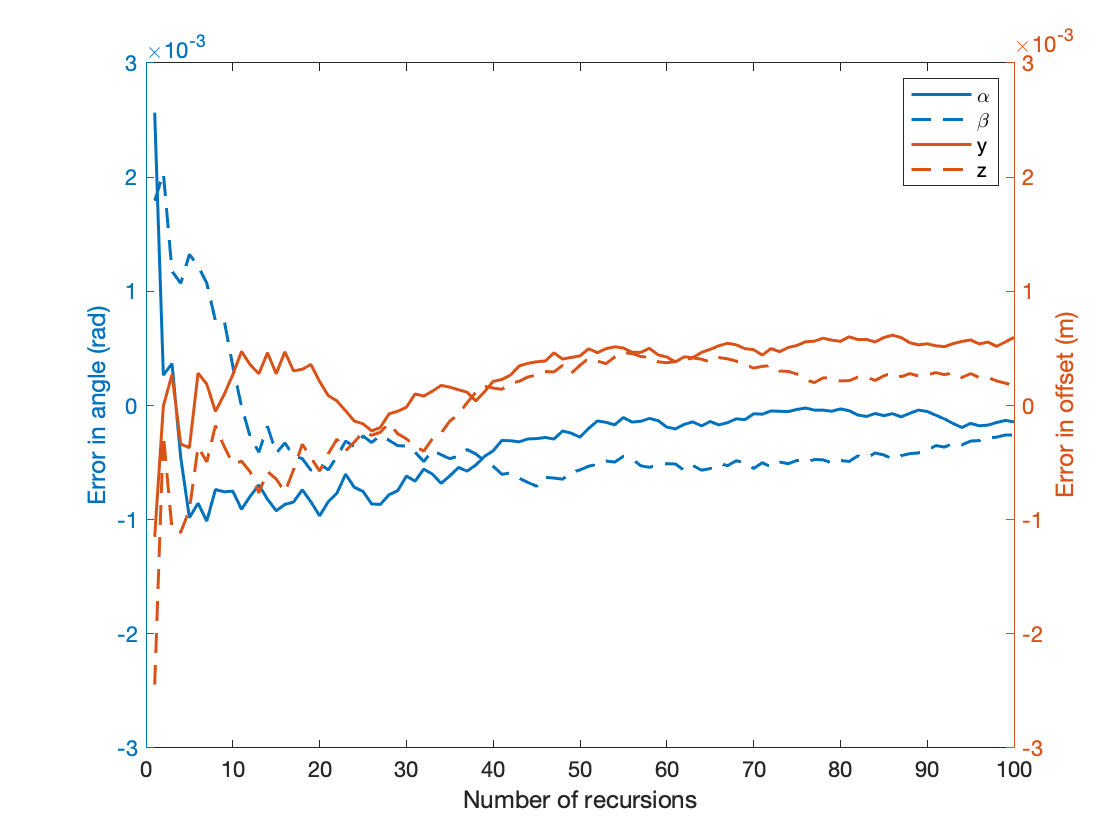

yyaxis left
plot(diffwxs,'LineWidth',1.5)
hold on
plot(diffwys,'LineWidth',1.5)
yyaxis right
plot(diffvxs,'LineWidth',1.5)
plot(diffvys,'LineWidth',1.5)
hold off

yyaxis left
ylim([-3e-3 3e-3])
ylabel('Error in angle (rad)')
yyaxis right
ylim([-3e-3 3e-3])
ylabel('Error in offset (m)')

legend('\alpha','\beta','y','z')

xlabel('Number of recursions')